初版：2021年12月11日

# シミュレーション　講義ノート No.3

#### 藤原　哉

#### 農林中央金庫

### 1.分散低減法Ⅱ

#### 1-1.  Stratified Sampling(層化抽出法）

　Stratified Samplingでは、乱数を生成する領域を分割し、各領域でシミュレーション値を求め、各領域の確率でシミュレーション値を加重平均することにより、全体の推定値を求める。

各領域でサンプリングすることによりサンプリングの偏りを抑えて分散低減を実現する。

例として、円周率を$4 \times \int_0^1 \sqrt{1-x^2} {\rm d} x$の定積分から求める問題を考える。講義ノートNo.2では $[0,1]$一様分布に従う乱数 $X_i$を用いて $\hat{\pi} \simeq \frac{1}{N} \sum_{i=1}^N \sqrt{1-X_i^2}$と評価している。Stratified Samplingでは積分領域 $[0,1]$を確率が等しくなるように例えば５分割 $[0,0.2], [0.2, 0.4], [0.4,0.6],[0.6,0.8],[0.8,1.0]$する。この分割した領域を $A_1,A_2,A_3,A_4,A_5$と表す。各領域の確率は $\mathbb{P}(A_j)=0.2, \forall j$である。各領域で一様分布に従う乱数 $X_{j,i}$を $N_j$個生成して $\hat{\pi} \sim \sum_{j=1}^{5} \mathbb{P}(A_j) \frac{1}{N_j} \sum_{i=1}^{N_j} X_{j,i}$と計算する。

clear;

f = @(x) sqrt(1-x.^2); 
nfig = 1; 
figure(nfig); gh = fplot(f,[0,1]);xticks(0:0.2:1.0);ax = gca; ax.XGrid = 'on'; gh.LineWidth = 2.0;
xs = 0.1:0.2:1.0; y = 0.1; txts = ["A_1"; "A_2"; "A_3"; "A_4"; "A_5"];
for iloop = 1:5
    text(xs(iloop),y,txts(iloop),'FontSize',12,'FontWeight',"bold");
end
title('積分範囲を５分割')

次に一般的な表現を確認する。生成する乱数の値域を 重なりのないM個の領域に分割する($A_1,\cdots,A_M, \ {\rm for} \ i \ne j, A_i \cap A_j = \phi$)。各領域の確率を $\mathbb{P}(A_i)$、各領域での期待値を $\mathbb{E}^{\mathbb{P}}\left[\cdot \vert A_i\right]$とすると


$$\mathbb{E}^{\mathbb{P}}\left[f(X)\right] = \sum_{i=1}^{M} \mathbb{P}(A_i) \mathbb{E}^{\mathbb{P}}\left[ f(X) \vert A_i\right]= \sum_{i=1}^{M} \mathbb{P}(A_i) \int_{A_i} f(X_i) {\rm d}\mathbb{P}(X_i \vert A_i) \simeq \sum_{i=1}^{M} \mathbb{P}(A_i) \frac{1}{N_i} \sum_{j=1}^{N_i} f(X_{i,j}) = \hat{f}(X)$$



$$X_{i,j} \sim \mathbb{P}\left(X \vert A_i)$$


となる。比較のために通常のモンテカルロ・シミュレーションによる推定を $\hat{f}^{full}(X)$とすると


$$\hat{f}^{full}(X) = \frac{1}{N} \sum_{i=1}^N f(X_i), \ X_i \sim \mathbb{P}(X)$$



$${\rm Var}\left( \hat{f}^{full}(X) \right) = \frac{1}{N^2} \sum_{i=1}^{N} {\rm Var}\left( f(X) \right) = \frac{1}{N} {\rm Var}\left( f(X) \right)$$


となる。

以下では $p_i = \mathbb{P}(A_i), q_i = \frac{N_i}{N}, N = \sum_{i=1}^M N_i$として、式変形を進めると


$$\hat{f}(X) = \sum_{i=1}^M p_i \frac{1}{N_i} \sum_{j=1}^{N_i} f(X_{i,j}) = \frac{1}{N}\sum_{i=1}^{M} \frac{p_i}{q_i} \sum_{j=1}^{N_i} f(X_{i,j})$$


となる。これより $\sigma_i^2 = {\rm Var}\left( f(X) \vert A_i \right)$とすると


$${\rm Var} \left( \hat{f}(X)\right) = \frac{1}{N^2} \sum_{i=1}^{M} \frac{p_i^2}{q_i^2} \sum_{j=1}^{N_i} {\rm Var} \left( f(X_{i,j}) \right)=\frac{1}{N^2} \sum_{i=1}^{M} \frac{p_i^2}{q_i^2} \sigma_i^2 N_i = \frac{1}{N} \sum_{i=1}^{M} \frac{p_i^2}{q_i} \sigma_i^2$$


となる。

$q_i$**の最適化**

ここで、 ${\rm Var}\left( \hat{f}(X) \right)$を最小にする $q_i^*$を探すことを考える。

 $\sum_{i=1}^{M} q_i = 1$なので $q_i^*$はラグランジュの未定乗数法で求めることができる。未定定数を $\lambda$として


$$\mathcal{L} = \frac{1}{N} \sum_{i=1}^{M} \frac{p_i^2}{q_i} \sigma_i^2 + \lambda \left( \sum_{i=1}^{M} q_i - 1 \right)$$


とする。 $q_i$で微分すると


$$\frac{\partial}{\partial q_i} \mathcal{L} = -\frac{1}{N}\frac{p_i^2}{q_i^2} \sigma_i^2 +\lambda = 0, \ \forall i$$


となるので$q_i = \frac{p_i \sigma_i}{\sqrt{\lambda N}}$とわかる。 $\sum_{i=1}^{M} q_i = 1$より $\sqrt{\lambda N} = \sum_{i=1}^{M} p_i \sigma_i$となるので


$$q_i^* = \frac{p_i \sigma_i}{\sum_{i=1}^{M} p_i \sigma_i}$$


である。このとき


$${\rm Var}\left( \hat{f}(X) \right) = \frac{1}{N} \sum_{i=1}^{M} \frac{p_i^2}{q_i^*} \sigma_i^2 = \frac{1}{N} \left( \sum_{i=1}^{M} p_i \sigma_i \right)^2$$


となる。

事前に $\sigma_i$が分からないのが一般的であるので 各分割 $A_i$で シミュレーションにより $\sigma_i$を推定（プレシミュレーション）して $q_i^*$を求めてからシミュレーションすることになる。

**簡便な方法**

$\sigma_i$を事前に推定せずに $q_i = p_i$とすることを考える。この方法は分散を最小化しないがプレシミュレーションを必要とせず手軽であるので実際にはよく使われている。

$q_i = p_i$とすると


$$\hat{f}(X) = \frac{1}{N} \sum_{i=1}^{M} \sum_{j=1}^{N_i} f(X_{i,j})$$



$${\rm Var} \left(\hat{f}(X) \right) = \frac{1}{N} \sum_{i=1}^{M} p_i \sigma_i^2 = \frac{1}{N} \mathbb{E} [\sigma_i^2] = \frac{1}{N} \mathbb{E} \left[ {\rm Var} \left( f(X) \vert A\right) \right]$$


となる。この方法でも分散低減になっていることを確認する。分散の定義より


$${\rm Var}\left( f(X) \right) = \mathbb{E}\left[f(X)^2\right] - \left( \mathbb{E}\left[ f(X) \right] \right)^2$$



$${\rm Var}(f(X) \vert A) = \mathbb{E}\left[ f(X)^2 \vert A \right] - \left( \mathbb{E}\left[f(X) \vert A \right] \right)^2$$


である。これより、


$$\mathbb{E}\left[ {\rm Var}(f(X) \vert A ) \right] = \mathbb{E}\left(f(X)^2\right] - \mathbb{E} \left[ \left(\mathbb{E}\left[f(X) \vert A \right] \right)^2 \right] = {\rm Var}\left(f(X)\right) + \left(\mathbb{E}\left[f(X)\right]\right)^2 - \mathbb{E}\left[ \left(\mathbb{E}\left[f(X) \vert A \right] \right)^2\right]$$


となる。また $\mathbb{E}\left[\mathbb{E}\left[f(X)\vert A\right] \right] = \mathbb{E}\left[f(X) \right]$であるので


$${\rm Var}\left(\mathbb{E}\left[f(X) \vert A \right] \right) = \mathbb{E}\left[ \left( \mathbb{E}\left[f(X) \vert A \right] \right)^2 \right] - \left(\mathbb{E}\left[ f(X) \right] \right)^2$$


となる。これを用いると


$$\mathbb{E}\left[ {\rm Var}\left(f(X) \vert A \right) \right] = {\rm Var}\left(f(X) \right) - {\rm Var} \left( \mathbb{E}\left[f(X)\vert A\right]\right) \le {\rm Var}\left(f(X)\right)$$


となるので、これより


$${\rm Var}\left( \hat{f}(X) \right) = \frac{1}{N} \mathbb{E}\left[{\rm Var}\left(f(X) \vert A\right)\right] \le \frac{1}{N} {\rm Var}\left(f(X)\right) = {\rm Var}\left( \hat{f}^{full}(X) \right)$$


となり、 $q_i = p_i$としても分散低減の効果があることがわかる。

**限界**

stratified samplingでは領域を分割し、その領域に対する確率がわかっていることが必要である。多次元で相関がある場合には領域分割の方法や領域に対する確率計算が複雑になる。

相関がある多次元の問題を扱う簡単な方法はコピュラである。特に正規コピュラを用いると計算が比較的容易になる。

元の同時分布関数 を$F(x_1,\cdots,x_n)$、元の周辺分布関数を $F_1(x_1),\cdots,F_n(x_n)$、 多次元標準正規分布の分布関数を $\Phi$、相関行列を $\varrho$、１次元標準正規の分布関数を $N$とすると


$$F(x_1,\cdots,x_n) = \Phi \left(N^{-1}\left(F_1(x_1)\right),\cdots, N^{-1}\left(F_n(x_n)\right), \varrho \right)$$


と表すことができる。 $\varepsilon_1,\cdots,\varepsilon_n$を独立な標準正規分布に従う確率変数とする。コレスキー分解より相関行列を $\varrho = LL^T$（ $L$は下三角行列）と表現する。さらに $\tilde{\varepsilon_1},\cdots, \tilde{\varepsilon_n}$を次のように定める。


$$\pmatrix{\tilde{\varepsilon_1} \cr \vdots \cr \tilde{\varepsilon_n}} = L \pmatrix{\varepsilon_1 \cr \vdots \cr \varepsilon_n}$$


これより $x_1 = F_1^{-1} \left( N(\tilde{\varepsilon_1})\right), \cdots, x_n = F_n^{-1}\left( N^{-1}(\varepsilon_n)\right)$となる。この方法では標準正規分布に従う乱数 $\varepsilon_1,\cdots,\varepsilon_n$を生成するときにstratified samplingを適用することになる。

この方法は計算自体は難しくないが、相関行列 $\varrho$の解釈は一般に困難である。

また、領域を分割することはグリッドを生成することと同じであるので多次元になると領域の数が指数的に増大する(次元呪い）。各次元の分割数を $N$、次元数を $d$とすると領域の数は $N^d$となる。例えば、10次元の問題で各次元の分割数を10とすると領域数は $10^{10}=$100億、分割数を20とすると $20^{10} \simeq$10兆となる。これより、次元数・分割数に大きな数を用いることは非現実的であることがわかる。

モンテカルロ・シミュレーションのメリットは多次元でも現実的な計算量で評価できることであるが、stratified samplingでは分散低減と引き換えに、そのメリットを失っていることになる。

#### 1-2. 数値例：円周率計算

$4\times \int_0^1 \sqrt{1-x^2} {\rm d}x$をシミュレーションで評価することで 円周率を推定する。生成する乱数の総数は一定として積分領域 $[0,1]$を分割無し(通常のモンテカルロ）、2分割、10分割、100分割した場合に推定値の信頼区間がどのようになるか確かめよ。シミュレーション数を1000,10000,100000としたときに結果がどうなるか確認せよ。参考として、シミュレーション数が1000での結果を示す。分割数１は通常のモンテカルロ・シミュレーションの結果である。この問題では stratfied samplingの効果は大きいことがわかる。

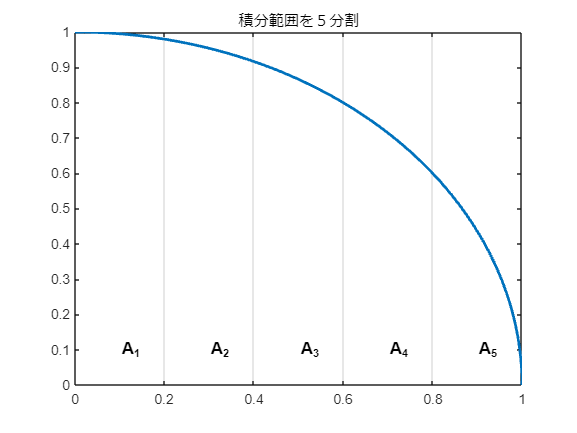

clear; 

rst1 = estPi(1);
rst2 = estPi(2);
rst3 = estPi(10);
rst4 = estPi(100); 


lower = [rst1.CILower;rst2.CILower;rst3.CILower;rst4.CILower];
upper = [rst1.CIUpper;rst2.CIUpper;rst3.CIUpper;rst4.CIUpper];

nfig = 2; 
figure(nfig);plot([upper,lower],'b*-');grid on; xlabel('分割数'); xticks(1:4); xticklabels(["1","2","10","100"]);hold on; 
plot(1:4,ones(1,4)*pi,'-'); title('stratified samplingによる\piの推定(Nsim=1000)'); 
legend('99%推定区間上限','99%推定区間下限','真値','location','best'); hold off;

#### 1-3. Latin Hypercubic sampling

stratified samplingの短所である多次元での計算困難を緩和するための方法としてLatin Hypercubic samplingがある。stratified samplingでは分割したすべての領域を用いるため多次元での領域数の指数関数的増大をもたらす。Latin Hypercubic samplingでは分割した領域の中から計算に用いる領域をサンプリングする。そのときに「出来るだけ偏りを少なく」サンプリングを行う。Latin Hypercubic samplingでは分割された領域の数に関係なくサンプル数を選ぶため、多次元の問題であっても現実的な計算時間で対応可能となる。

例として、２次元の領域 $[0,1]\times[0,1]$からランダムに点を選ぶことを考える。単純な方法は独立な $[0,1]$一様乱数を２つ生成して $(x_i,y_i)$として点を選ぶ。stratified samplingでは $[0,1]\times[0,1]$を分割する。例えば $[0,1]$を10分割して、 $10\times10$の領域に分割する。そして、各領域（全部で100となる）で乱数を生成して $(x_i,y_i)$を決める。Latin hypercubic samplingではstratified samplingと同様に各次元で分割を行うが、すべてを利用するのではなく領域の重複がないように選択する。サンプリング例を図に示す。青丸が一様乱数から選んだ10点である。stratified samplingでは100個の領域全てでサンプリングを行う（点は示していない）。赤丸がLatin Hypercubic samplingで選んだ10点である。各行・各列に1点入るようにサンプリングしている(このことが”出来るだけ偏りを少なく”を表している）。

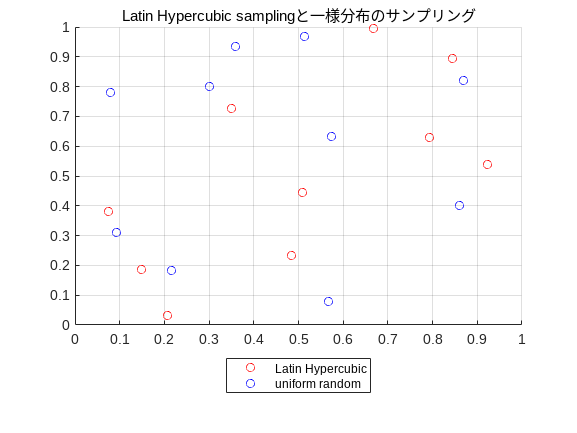

clear; 

nfig = 3; 
vlhs = lhsdesign(10,2,'smooth',"on");
figure(nfig); scatter(vlhs(:,1),vlhs(:,2),'red'); grid on; xticks(0:0.1:1.0); yticks(0:0.1:1.0); 
title('Latin Hypercubic samplingと一様分布のサンプリング');
hold on; 
vrnd = rand(10,2); 
figure(nfig); scatter(vrnd(:,1),vrnd(:,2),'blue'); legend('Latin Hypercubic','uniform random','Location',"southoutside"); 
hold off;

Matlabには Latin Hybercubic samplingのための関数 lhsdesignが用意されている。上図でのLatin Hypercubic samplingの点は以下のように関数を実行している。

詳細はMatlabのドキュメントを参照のこと。

#### 1-4. 数値例：円周率計算

円周率をシミュレーションで求める方法は色々あるが、ここでは球の体積を用いる。半径1の球のうち $x \in [0,1], y\in[0,1],z\in[0,1]$での体積は


$$V = \int_0^1 \int_0^{\sqrt{1-x^2}} \sqrt{1-x^2-y^2} {\rm d}y {\rm d}x$$


と積分を用いて表すことができる。Vは球の体積の $\frac{1}{8}$であるので $V = \frac{4\pi}{3} \times  \frac{1}{8} = \frac{\pi}{6}$である。　積分範囲を下図に示す。

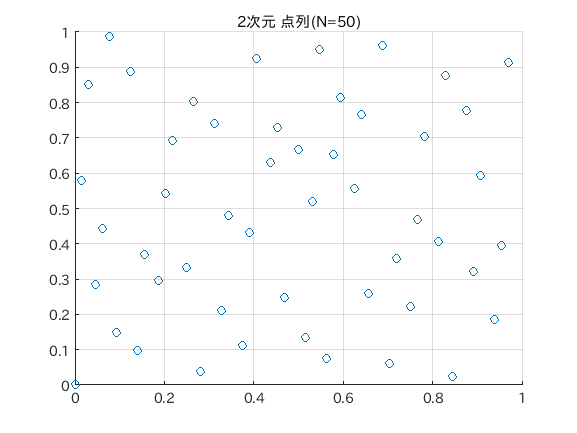

clear; 

% 極座標表示
xfun = @(tht,phi) sin(tht).*cos(phi); 
yfun = @(tht,phi) sin(tht).*sin(phi);
zfun = @(tht,phi) cos(tht);

%
nfig = 4;
figure(nfig); gh = fsurf(xfun,yfun,zfun,[0,pi/2],'EdgeColor',"none");grid on; xlabel('x'); ylabel('y'); zlabel('z');
title('積分領域');view(20,30);

$V$をシミュレーションで求めるために期待値で表現する。

xを所与とすると


$$\int_0^{\sqrt{1-x^2}} \sqrt{1-x^2-y^2}{\rm d}y = \mathbb{E}\left[ \left. \sqrt{1-x^2} \sqrt{1-x^2-Y^2} \right\vert x \right]$$


と表される。ただし、 $Y$は $\left[0,\sqrt{1-x^2}\right]$一様分布に従う確率変数である。よって、


$$V = \int_0^1 \mathbb{E} \left[ \left. \sqrt(1-x^2) \sqrt{1-x^2-Y^2} \right\vert x \right] {\rm d} x = \mathbb{E}\left[ \mathbb{E}\left[ \left. \sqrt{1-X^2}\sqrt{1-X^2-Y^2} \right\vert X \right] \right]$$


となる。ただし、 $X$は $[0,1]$一様分布に従う確率変数である。 

これより、２次元の一様分布に従う乱数 $\left(x_1, \sqrt{1-x_1^2} x_2\right)$を生成することでシミュレーションにより $V$を推定することができる。 $\pi \sim 6 \times V$と円周率が推定されることになる。 

$(x_1,x_2)$の乱数生成にLatin Hypercubic samplingを用いる。シミュレーション例を下に示す。分割数１は通常のモンテカルロ・シミュレーションである。この例では、Latin Hypercubic samplingは通常のモンテカルロ・シミュレーションよりも誤差は小さくなるが、分割数を大きくしても誤差が小さくなっていない。

clear;

Nsim = 1000; 

rst1 = estPiBySphere(1,Nsim,'method','MC');
rst2 = estPiBySphere(10,Nsim,'method','LHC');
rst3 = estPiBySphere(100,Nsim,'method','LHC');
rst4 = estPiBySphere(1000,Nsim,'method','LHC');

lower = [rst1.CILower;rst2.CILower;rst3.CILower;rst4.CILower];
upper = [rst1.CIUpper;rst2.CIUpper;rst3.CIUpper;rst4.CIUpper];

nfig = 5; 
figure(nfig);plot([upper,lower],'b*-');grid on; xlabel('分割数'); xticks(1:4); xticklabels(["1","10","100","1000"]);hold on; 
plot(1:4,ones(1,4)*pi,'-'); title('Latin Hypercubic samplingによる\piの推定(Nsim=1000)'); 
legend('99%推定区間上限','99%推定区間下限','真値','location','best'); hold off; 

#### 分散低減法に関する個人的な見解

個人的な経験では、antithetic samplingとimportance samplingは問題に応じて使うことはあるが、それ以外の方法を実務で用いたことはない。

色々な分散低減法が開発された時代では現在と比べてコンピュータの計算処理能力が低く、少ない計算量で精度を上げる工夫をすることに大きな意味があったのだろう。現在は個人レベルでも簡単に大容量メモリーと並列演算を行う環境にアクセスできるため、多くの問題をシンプルな方法で十分な試行回数を現実的な計算時間で実行できるようになっていると思う。

### 2. 準モンテカルロ法

　準モンテカルロ法では、一様にサンプル点を配置することにより誤差低減を行う。モンテカルロ法の疑似乱数の評価基準は一様分布の統計量であったが、準モンテカルロ法では点列の一様性が基準となる。

次元をsとして $[0,1)^s$での $N$個の点列を $P_N([0,1)^s)$とし、任意の領域 $I \subset [0,1)^s$とする。領域 $I$に含まれる点列を $I \cap P_N([0,1)^s)$とすると、点列の一様性の定義は、


$$\lim_{N\rightarrow \infty} \frac{\# \left( I \cap P_N([0,1)^s)\right)}{N} = \left\vert I \right\vert$$


となることである。ただし、 $\# ()$は点列の点の数、 $\vert I \vert$は領域 $I$の体積を表している。

このことを利用して以下のように $s$次元の点列 $P_N$のDiscrepancy $D_s(P_N)$を以下のように定義する。


$$D_s(P_N) = \sup_{I \in [0,1)^s} \left\vert \frac{\#(I \cap P_N)}{N} - \vert I \vert  \right\vert$$


また、 $\left\vert \frac{\#(I \cap P_N)}{N} - \vert I \vert  \right\vert$はlocal Discrepancyと呼ばれる。

さらに領域 $I$が必ず原点を含む、つまり、 $I_0 = [0, x_1) \times \cdots [0,x_s)$ に限定されるときのDisrepancyはStar-Discrepancyと呼ばれ $D_s^* (P_N)$と表す。

$D_t^*(P_N)$により一様性を評価する。

例として2次元の点列 $(N=50)$が下の図のように与えられているとき、 $I_0 = [0,0.2)\times [0, 0.2)$とするとlocal Discrepancyは


$$\left\vert \frac{\#(I_0 \cap P_N)}{N} - \vert I_0 \vert  \right\vert = \left\vert \frac{3}{50} - 0.2\times 0.2 \right\vert = 0.02$$


となる。

clear;

tmpfun = genHaltonStreamFun(2);
vs = tmpfun(50);
nfig = 6; 
figure(nfig); scatter(vs(:,1),vs(:,2));grid; title('2次元 点列(N=50)'); 

#### 2-1. Low Discrepancy Sequence(LDS)：超一様分布列

$s$次元の $N$個の点列 $P_N$が以下の関係を満たすとき $P_N$は Low Discrepnacy Sequence (LDS)：超一様分布列と呼ばれる。


$$D_s^*(P_N) \le c_s \frac{\left( \log N \right)^s }{N}$$


ただし、 $c_s$は次元 $s$のみに依存する定数である。

#### LDSの例

　与えられた点列の Star-Discrepanyを計算することは数学的なハードルが高いため、ここでは、よく知られているLDSのうち

van der Corput列、Halton列、Sobol列の作り方のイメージを示す。実際にLDSを使うときにはライブラリーを活用する。

**van der Corput列**

　van der Corput列は1次元のLDSであり、Halton列、Sobol列など多次元のLDSの基礎として使われている。

van der Corput列の作り方は次の通りである。

- 素数を基底として選ぶ(選んだ素数をbとする）

- 整数 $i$の基底 bでの展開を $i = a_0(i) + a_1(i)b + a_2(i) b^2 + \cdots + a_n(i) b^n + \cdots$とする。

- 整数 $i$に対する van der Corput列での値を $v_i = \frac{a_0(i)}{b} + \frac{a_1(i)}{b^2} + \frac{a_2(i)}{b^3} + \cdots + \frac{a_n(i)}{b^{n+1}} + \cdots$とする。

- $i = 0, 1, 2, \cdots,$に対応する点列 $v_0, v_1, v_2, \cdots$がvan der Corput列である。

$b=2$の時のvan der Corput列の最初の10項を計算する。

$i = 0$のとき 基底2での展開は $0$、よって、$v_0=0$

$i=1$のとき 基底2での展開は 1、よって、 $v_1=\frac{1}{2}$

$i=2$のとき 基底2での展開は $0 + 1\cdot 2$、よって、 $v_2 = \frac{0}{2} + \frac{1}{2^2} = \frac{1}{4}$

$i=3$のとき 基底2での展開は $1 + 1\cdot2$、よって、 $v_3 = \frac{1}{2} + \frac{1}{2^2} = \frac{1}{2} + \frac{1}{4} = \frac{3}{4}$

$i=4$のとき 基底2での展開は $0 + 0\cdot 2 + 1\cdot 2^2$、よって、 $v_4 = \frac{0}{2} + \frac{0}{2^2} + \frac{1}{2^3} = \frac{1}{8}$

$i=5$のとき 基底2での展開は $1 + 0\cdot 2 + 1\cdot 2^2$、よって、 $v_5 = \frac{1}{2} + \frac{0}{2^2} + \frac{1}{2^3} = \frac{5}{8}$

$i=6$のとき 基底2での展開は $0 + 1\cdot 2 + 1\cdot 2^2$、よって、 $v_6 = \frac{0}{2} + \frac{1}{2^2} + \frac{1}{2^3} = \frac{3}{8}$

$i=7$のとき 基底2での展開は $1 + 1\cdot 2 + 1\cdot 2^2$、よって、 $v_7 = \frac{1}{2} + \frac{1}{2^2} + \frac{1}{2^3} = \frac{7}{8}$

$i=8$のとき 基底2での展開は $0 + 0\cdot 2 + 0\cdot 2^2 + 1\cdot 2^3$、よって、 $v_8 = \frac{0}{2} + \frac{0}{2^2} + \frac{0}{2^3} + \frac{1}{2^4}= \frac{1}{16}$

$i=9$のとき 基底2での展開は $1 + 0\cdot 2 + 0\cdot 2^2 + 1\cdot 2^3$、よって、 $v_9 = \frac{1}{2} + \frac{0}{2^2} + \frac{0}{2^3} + \frac{1}{2^4}= \frac{9}{16}$

$i=10$のとき 基底2での展開は $0 + 1\cdot 2 + 0\cdot 2^2 + 1\cdot 2^3$、よって、 $v_{10} = \frac{0}{2} + \frac{1}{2^2} + \frac{0}{2^3} + \frac{1}{2^4}= \frac{5}{16}$

**Halton列**

　Halton列は van der Corput列を用いた多次元のLDSである。

作り方は 1番目の次元は 基底2の van der Corput列、2番目の次元は基底3のvan der Corput列、…、 $s$番目の次元は $s$番目の素数を基底とする van der Corput列とする。

2次元のHalton列は基底2と基底３のvan der Corput列となるので最初の10項は次のようになる。


$$v_0 = (0,0), v_1 = \left(\frac{1}{2},\frac{1}{3} \right), v_2 = \left( \frac{1}{4}, \frac{2}{3} \right), v_3 = \left( \frac{3}{4},\frac{1}{9} \right), v_4 = \left(\frac{1}{8},\frac{4}{9} \right), v_5 = \left( \frac{5}{8}, \frac{7}{9} \right)$$



$$v_6 = \left( \frac{3}{8}, \frac{2}{9} \right), v_7 = \left( \frac{7}{8}, \frac{5}{9} \right), v_8 = \left(\frac{1}{16},\frac{8}{9} \right), v_9 = \left( \frac{9}{16},\frac{1}{27}\right),v_{10} = \left(\frac{5}{16}, \frac{10}{27} \right)$$


**Sobol列**

  Sobol列は基底２のvan der Corput列を用いた多次元のLDSである。

Sobol列の1番目の次元は基底２のvan der Corput列である。2番目以降の次元の作り方は以下の通りである。

整数 $i$の基底 2による展開の係数をベクトル $a(i) = \left( a_0(i), a_1(i), \cdots a_n(i) \right)'$として表す。次元 $s$に対応する生成行列 $C_s$を用意して


$$\tilde{a}_s(i) =\left( \tilde{a}_{s,0} (i), \cdots, \tilde{a}_{s,n}(i) \right)' =  C_s a(i)　{\rm mod} \ 2$$


とする。 ${\rm mod \ 2}$は2で割ったときの余りを表す。これより、整数 $i$に対応するSobol列の次元 $s$の値 $v_{i,s}$は次のように計算される。


$$v_{i,s} = \frac{\tilde{a}_{s,0}(i)}{2} + \frac{\tilde{a}_{s,1}(i)}{2^2} + \cdots + \frac{\tilde{a}_{s,n}(i)}{2^{n+1}}$$


各次元の生成行列 $C_s$は位数２の有限体($F_2$)上の原始多項式を用いて作られるが、理論は複雑であるのでここではレシピ的に作り方を示す。

選んだ原始多項式が $x^q + c_1 x^{q-1} + \cdots c_{q-1} x + 1$とする。このとき $m_1,\cdots m_q$を所与として


$$m_j = c_1 m_{j-1} 2 \oplus c_2 m_{j-2} 2^2 \oplus \cdots \oplus c_{q-1} m_{j-q+1}2^{q-1} \oplus m_{j-q} 2^q \oplus m_{j-q}$$


と $m_j$を生成する。ただし $\oplus$は二進数でのビットごとの足し算を表す。初期値 $m_i, i=1,\cdots,q$は $2^i$以下の奇数である。

$C_s$の $j$番目の列ベクトルは $v_j = \frac{m_j}{2^j}$の二進数表示での小数点以下の数字列となる。

例として原始多項式が x+1の場合に生成行列 $C$を求める。

$x+1$の場合$q=1$であるので $m_j$の漸化式は


$$m_j = m_{j-1} 2 \oplus m_{j-1}$$


となる。

 $C$の第5列ベクトルまで求めてみる。$m_1 = 1$とし、 $()_b$を二進数表示とすると


$$m_1 = 1 = (1)_b$$



$$m_2 = 2 \oplus 1 = (11)_b = 3$$



$$m_3 = 3*2 \oplus 3 = (101)_b = 5$$



$$m_4 = 5*2 \oplus 5 = (1111)_b = 15$$



$$m_5 = 15*2 \oplus 15 = (10001)_b = 17$$


となる。これより

$v_1 = (0.1)_b, v_2 = (0.11)_b, v_3 = (0.101)_b, v_4 = (0.1111)_b, v_5 = (0.10001)_b$となるので


$$C= \pmatrix{1 & 1 & 1 & 1 & 1 \cr 0 & 1 & 0 & 1 & 0 \cr 0 & 0 & 1 & 1 & 0 \cr 0 & 0 & 0 & 1 & 0 \cr 0 & 0 & 0 & 0 & 1}$$


となる。この生成行列を用いて最初の10項を求める。


$$\tilde{a}(0) = C \pmatrix{0 \cr 0 \cr 0 \cr 0 \cr 0} {\rm mod} \ 2= \pmatrix{0 \cr 0 \cr 0 \cr 0 \cr 0}$$


対応する数列の値は$v_0 = 0$である。


$$\tilde{a}(1) = C \pmatrix{1 \cr 0 \cr 0 \cr 0 \cr 0} {\rm mod} \ 2 = \pmatrix{1 \cr 0 \cr 0 \cr 0 \cr 0}$$


対応する数列の値は$v_1 = \frac{1}{2}$である。


$$\tilde{a}(2) = C \pmatrix{0 \cr 1 \cr 0 \cr 0 \cr 0} {\rm mod} \ 2 = \pmatrix{1 \cr 1 \cr 0 \cr 0 \cr 0}$$


対応する数列の値は$v_2 = \frac{1}{2} + \frac{1}{2^2} = \frac{3}{4}$である。


$$\tilde{a}(3) = C \pmatrix{0 \cr 1 \cr 1 \cr 0 \cr 0} {\rm mod} \ 2 = \pmatrix{0 \cr 1 \cr 0 \cr 0 \cr 0}$$


対応する数列の値は$v_3 = \frac{1}{2^2} = \frac{1}{4}$である。


$$\tilde{a}(4) = C \pmatrix{0 \cr 0 \cr 1 \cr 0 \cr 0} {\rm mod} \ 2 = \pmatrix{1 \cr 0 \cr 1 \cr 0 \cr 0}$$


対応する数列の値は$v_4 = \frac{1}{2} + \frac{1}{2^3} = \frac{5}{8}$である。


$$\tilde{a}(5) = C \pmatrix{1 \cr 0 \cr 1 \cr 0 \cr 0} {\rm mod} \ 2 = \pmatrix{0 \cr 0 \cr 1 \cr 0 \cr 0}$$


対応する数列の値は$v_5 = \frac{1}{2^3} = \frac{1}{8}$である。


$$\tilde{a}(6) = C \pmatrix{0 \cr 1 \cr 1 \cr 0 \cr 0} {\rm mod} \ 2 = \pmatrix{0 \cr 1 \cr 1 \cr 0 \cr 0}$$


対応する数列の値は$v_6 = \frac{1}{2^2} + \frac{1}{2^3} = \frac{3}{8}$である。


$$\tilde{a}(7) = C \pmatrix{1 \cr 1 \cr 1 \cr 0 \cr 0} {\rm mod} \ 2 = \pmatrix{1 \cr 1 \cr 1 \cr 0 \cr 0}$$


対応する数列の値は$v_7 = \frac{1}{2} + \frac{1}{2^2} + \frac{1}{2^3} = \frac{7}{8}$である。


$$\tilde{a}(8) = C \pmatrix{0 \cr 0 \cr 0 \cr 1 \cr 0} {\rm mod} \ 2 = \pmatrix{1 \cr 1 \cr 1 \cr 1 \cr 0}$$


対応する数列の値は$v_8 = \frac{1}{2} + \frac{1}{2^2} + \frac{1}{2^3} + \frac{1}{2^4} = \frac{15}{16}$である。


$$\tilde{a}(9) = C \pmatrix{1 \cr 0 \cr 0 \cr 1 \cr 0} {\rm mod} \ 2 = \pmatrix{0 \cr 1 \cr 1 \cr 1 \cr 0}$$


対応する数列の値は$v_9 = \frac{1}{2^2} + \frac{1}{2^3} + \frac{1}{2^4} = \frac{7}{16}$である。


$$\tilde{a}(10) = C \pmatrix{0 \cr 1 \cr 0 \cr 1 \cr 0} {\rm mod} \ 2 = \pmatrix{0 \cr 0 \cr 1 \cr 1 \cr 0}$$


対応する数列の値は$v_{10} = \frac{1}{2^3} + \frac{1}{2^4} = \frac{3}{16}$である。

この例では生成行列 $C$の第5列まで求めたが、 $m_j$の漸化式を用いて任意の列数の$C$を計算することができる。

異なる原始多項式を選ぶと $m_j$の漸化式の形が変わるが、計算方法は同じようにして別の生成行列 $C$を求めることができる。

原始多項式が $x^2 + x + 1$とすると $q=2, c_1 = 1$となるので対応する漸化式は

$m_1 = 1, m_2 = 1$として $j \ge 3$に対して


$$m_j = c_1 m_{j-1} 2 \oplus m_{j-1} 2^2 \oplus m_{j-2}$$


となる。この漸化式をもとに $m_1, m_2, \cdots$を計算して 生成行列 $C$を算出する。その後は 原始多項式が$x+1$のときと同じ計算方法により数列を計算する。

必要な次元数の数だけ原始多項式を用意すれば対応する生成行列 $C$が計算出来るので多次元のSobol列を作ることができる。

#### 2-2. 数値例：円周率の計算

MatlabではStatistics and Machine Learning Toolboxで Halton列、Sobol列を生成する関数が用意されている（都立大BS学生であれば利用可能）。

以下のようにMatlabの関数を組み合わせることでSobol列／Halton列を用いてシミュレーションが可能となる。

Latin Hypercubic samplingと同様に球の体積の算出から円周率を求めるシミュレーションを乱択化Sobol列／Halton列で行い、通常のモンテカルロ・シミュレーションと比較する。なお、SkipとLeapは以下のシミュレーションでは設定していない。この例ではSobol/Haltonともに通常のモンテカルロ・シミュレーションより収束がよい。Sobol/Haltonでの優劣はこの例からはわからない。

clear;

Nsims = [100;1000;10000];

rstMC1 = estPiBySphere(1,Nsims(1),'method','MC'); 
rstSobol1 = estPiBySphere(1,Nsims(1),'method','Sobol');
rstHalton1 = estPiBySphere(1,Nsims(1),'method','Halton');

rstMC2 = estPiBySphere(1,Nsims(2),'method','MC'); 
rstSobol2 = estPiBySphere(1,Nsims(2),'method','Sobol');
rstHalton2 = estPiBySphere(1,Nsims(2),'method','Halton');

rstMC3 = estPiBySphere(1,Nsims(3),'method','MC'); 
rstSobol3 = estPiBySphere(1,Nsims(3),'method','Sobol');
rstHalton3 = estPiBySphere(1,Nsims(3),'method','Halton');

lowerMC = [rstMC1.CILower; rstMC2.CILower; rstMC3.CILower];
upperMC = [rstMC1.CIUpper; rstMC2.CIUpper; rstMC3.CIUpper];

lowerSobol = [rstSobol1.CILower; rstSobol2.CILower; rstSobol3.CILower];
upperSobol = [rstSobol1.CIUpper; rstSobol2.CIUpper; rstSobol3.CIUpper];

lowerHalton = [rstHalton1.CILower; rstHalton2.CILower; rstHalton3.CILower];
upperHalton = [rstHalton1.CIUpper; rstHalton2.CIUpper; rstHalton3.CIUpper];

nfig = 7; 
figure(nfig); semilogx(Nsims,[upperMC,lowerMC],'b.-'); grid; xlabel('Nsim'); hold on; 
semilogx(Nsims,[upperSobol,lowerSobol],'r^-'); semilogx(Nsims,[upperHalton,lowerHalton],'g*-'); 
semilogx(Nsims,pi*ones(size(Nsims)),'-');
title('Sobol/Halton Sequenceの効果'); 
legend('通常MC 99%上限','通常MC 99%下限','乱択化Sobol 99%上限','乱択化Sobol 99%下限','乱択化Halton 99%上限','乱択化Halton 99%下限','真値','location',"best");
hold off;

#### ローカル関数

stratified sampling

function rst = estPi(ndiv,Nsim)
    % stratified samplingによる円周率の推定
    arguments
        ndiv (1,1) {mustBeInteger,mustBePositive}
        Nsim (1,1) {mustBeInteger,mustBePositive} = 1000
    end
    Nt = 100; 
    alp = 0.01; 
    
    f = @(x) 4*sqrt(1-x.^2); 
    
    vs = zeros(Nt,1);
    for iloop = 1:Nt
        for jloop = 1:ndiv
            p = 1.0/double(ndiv); 
            vs(iloop) = vs(iloop) + p*mean(f(p*rand(Nsim,1)+p*(jloop-1)));
        end
    end
    rst = estConfidenceInterval(vs,alp);
end

Latin Hypercubic sampling・Sobol Sequence・Halton Sequence

function rst = estPiBySphere(ndiv,Nsim,options)
    %
    arguments
        ndiv (1,1) {mustBeInteger,mustBePositive}
        Nsim (1,1) {mustBeInteger,mustBePositive}
        options.method {mustBeMember(options.method,{'MC','LHC','Sobol','Halton'})} = 'LHC'
    end
    Ndim = 2; 
    switch options.method
        case 'LHC'
            myrnd = @() mkrvsImpl(ndiv,Nsim/ndiv);
        case 'MC'
            myrnd = @() rand(Nsim,Ndim);
        case {'Sobol','Halton'}
            tmpfun = genLDSStreamFun(Ndim,'method',options.method);
            myrnd = @() tmpfun(Nsim);
        otherwise
            error('unexpected method');
    end
    
    Nt = 10; 
    alp = 0.01; 
    vs = zeros(Nt,1); 
    
    f = @(xs) 6*sqrt(1-sum(xs.^2,2)); 
    
    for iloop = 1:Nt
        xs = myrnd();
        tmpx = sqrt(1-xs(:,1).^2);
        xs(:,2) = tmpx.*xs(:,2); 
        vs(iloop) = mean(tmpx.*f(xs));
    end
    
    rst = estConfidenceInterval(vs,alp); 

    % Latin Hypercubic samplingでの乱数生成のための補助関数 
    % [0,1]のndiv分割での乱数をnloop回繰り返す
    function vs = mkrvsImpl(ndiv,nloop)
        %
        vs = zeros(ndiv*nloop,Ndim); 
        for jloop = 1:nloop
            istart = 1 + ndiv*(jloop-1);
            iend = ndiv*jloop;
            vs(istart:iend,:) = lhsdesign(ndiv,Ndim);
        end
    end
    
end

準モンテカルロ

function vfun = genLDSStreamFun(ndim,options)
    %
    arguments
        ndim (1,1) {mustBeInteger}
        options.method {mustBeMember(options.method,{'Sobol','Halton'})} = 'Sobol'
    end
    
    switch options.method
        case 'Sobol'
            vfun = genSobolStreamFun(ndim);
        case 'Halton'
            vfun = genHaltonStreamFun(ndim);
        otherwise
            error('unexpected LDS type'); 
    end
    
end

function vfun = genSobolStreamFun(ndim)
    % Sobol列での乱択化ストリーム関数を返す
    arguments
        ndim (1,1) {mustBeInteger}
    end
    p = sobolset(ndim); 
    p = scramble(p,'MatousekAffineOwen');
    q = qrandstream(p); 
    
    vfun = @(Nsim) qrand(q,Nsim);
end

function vfun = genHaltonStreamFun(ndim)
    % Halton列での乱択化ストリーム関数を返す
    arguments
        ndim (1,1) {mustBeInteger}
    end
    
    p = haltonset(ndim);
    p = scramble(p,'RR2');
    q = qrandstream(p);
    
    vfun = @(Nsim) qrand(q,Nsim); 
    
end